# MATLAB Assignment 3 Phase 2: Further Exploring Directional Blur

Authors:  Gabriel Garcia, S Hassan Shaikh, Jordan Chung-Lee

I will be further exploring directional blur in this example by expanding upon the functionality in the example generated by ChatGPT.

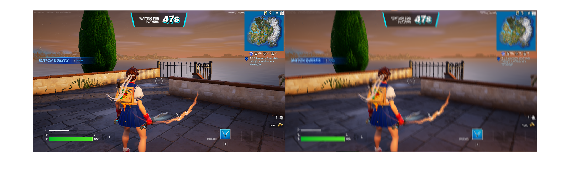

% Get image input
image = imread("C:\Users\gabeg\OneDrive\Documents\College\CAP4401\Gabe_G_Jordan_C_Hassan_S_CAP4401_Assignment_3\AliasedImage.png");

% Define the strength of the blur (adjust as needed)
blur_strength = 13;

% Convert the image to double
image = im2double(image);

% Get the size of the image
[rows, cols, ~] = size(image);

% Generate select an angle between 0 and 360 degrees
angle = 108;

% Create a directional filter
h = fspecial('motion', blur_strength, angle);

% Apply the filter to the image
blurred_image = imfilter(image, h, 'conv', 'circular');

% Display the original and blurred images
montage({image, blurred_image});

This example has been expanded upon by allowing the user to select their own input image instead of using a hard coded test image, allowing them to adjust the strength of the blur, and allowing them to choose the direction of the blur instead of it being a randomly generated value between 0 and 360 degrees.